# Jueves 11 noviembre

Capítulo 1: Introduccion a matlab

Estudiante: Victor Asanza

Materia: Simulación de Sistemas Eléctricos

Dataset: [https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dtaset)

Frecuencia de muestreo: 4Hz

**Paso1: Cargar un archivo .mat con frecuencia de muestreo de 1sample / 15min**

clear;%borra el worskpace
clc;%borra el comand windiw
path=fullfile('./datamean.mat');
data=load(path);
data=struct2cell(data);
data=data{1,1};%table
plot(data);%datos originales
title('Grafica de consumo con una muestreo cada 15 minutos');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP','Temp.','CPU','RAM');
xlabel('Muestras cada 15 minutos');
ylabel('Valor por variable');

**Ejemplo 4: Trabajar con una de las variables**

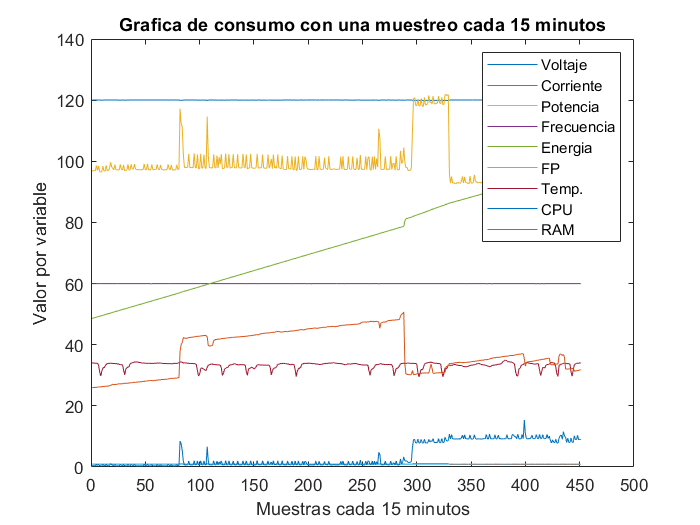

prompt = 'Seleccionar una de las variables (1-9)';

x = input(prompt) %columna para seleccionar la variable
variable=data(:,x);
datastats(variable)


x = 1

plot(variable);%datos originales
title('Variable con una muestreo cada 15 minutos');

ans = struct with fields:
       num: 451
       max: 120.0674
       min: 119.9012
      mean: 120.0236
    median: 120.0337
     range: 0.1661
       std: 0.0345


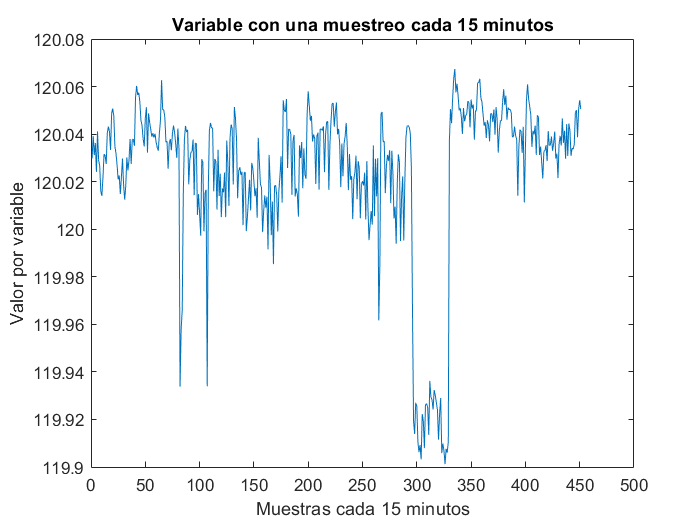

%legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP','Temp.','CPU','RAM');
xlabel('Muestras cada 15 minutos');
ylabel('Valor por variable');